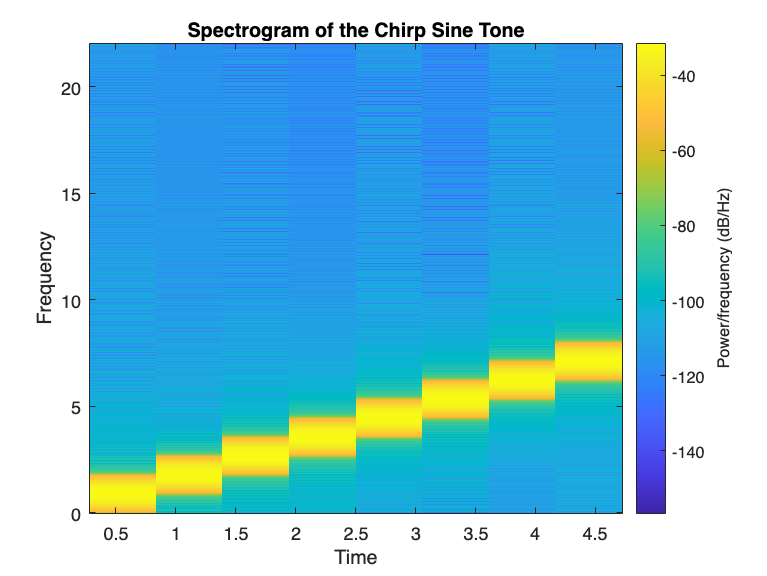

% Read WAV file
[audio, Fs] = audioread('1.wav');

% Duration of audio file
duration = length(audio) / Fs;

% Time vector
t = linspace(0, duration, length(audio));

% Frequency range
f_start = 0;
f_end = 8000; 

% Make chirp sine tone
chirp_tone = chirp(t, f_start, duration, f_end);

% Play chirp sine tone
sound(chirp_tone, Fs);

% Save chirp sine tone to WAV file
filename = 'Carrion-chirptone.wav';
audiowrite(filename, chirp_tone, Fs);

% Plot spectrogram
spectrogram(chirp_tone, [], [], [], Fs, 'yaxis');
title('Spectrogram of the Chirp Sine Tone');
xlabel('Time');
ylabel('Frequency');


% Save spectrogram
saveas(gcf, 'chirp_sine_tone_spectrogram.png');